# ポアソン分布を活用したサッカー予測

clear;clc;close all;

平均得点(muGF, Goals for)，平均失点(muGA, Goals against)，試合数を設定する．

muGF=1.8;
muGA=0.9;
numMatches=34;

各得点の確率を算出する

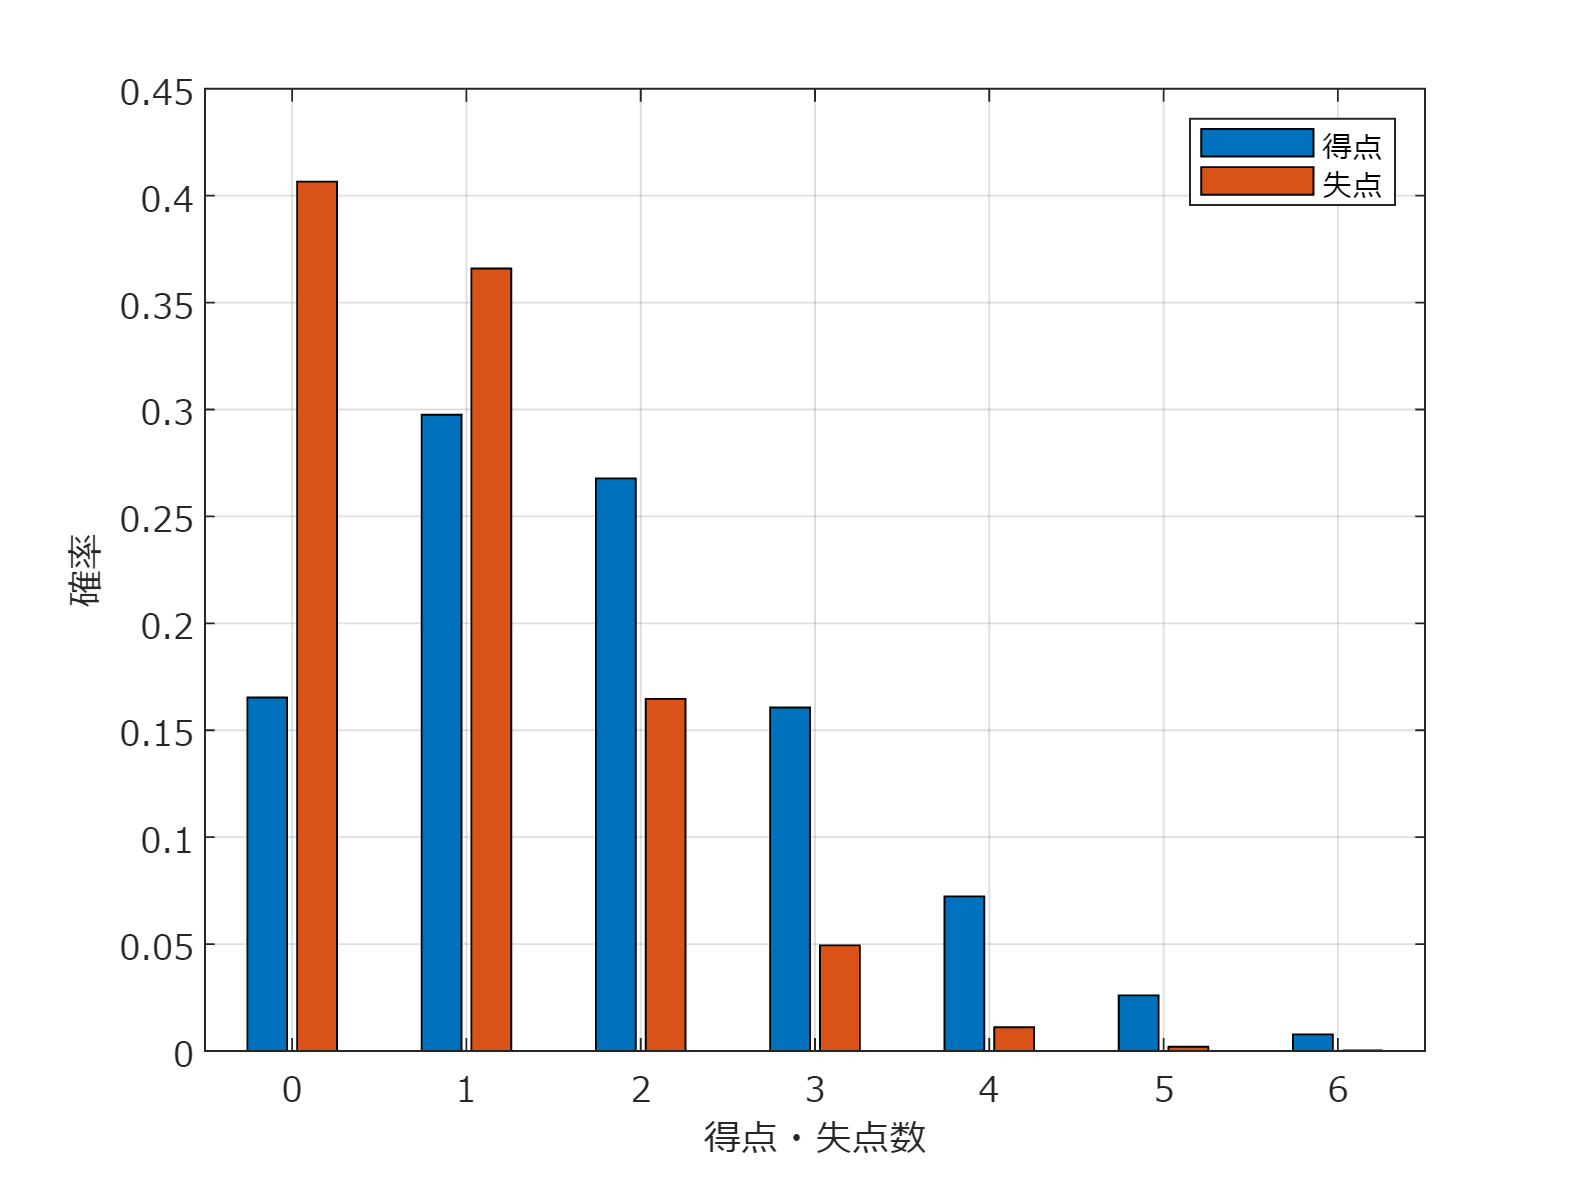

bins=0:12;
pGF=poisspdf(bins,muGF);
pGA=poisspdf(bins,muGA);
figure
bar(bins,[pGF;pGA]);set(gca,'fontname','メイリオ');grid on;
legend({'得点','失点'});
xlim([-0.5 6.5]);
xlabel('得点・失点数');ylabel('確率');

% exportgraphics(gcf,'fig_poissonSimulator-goals.pdf');

得失点それぞれを独立と仮定して，組み合わせごとの確率を計算する

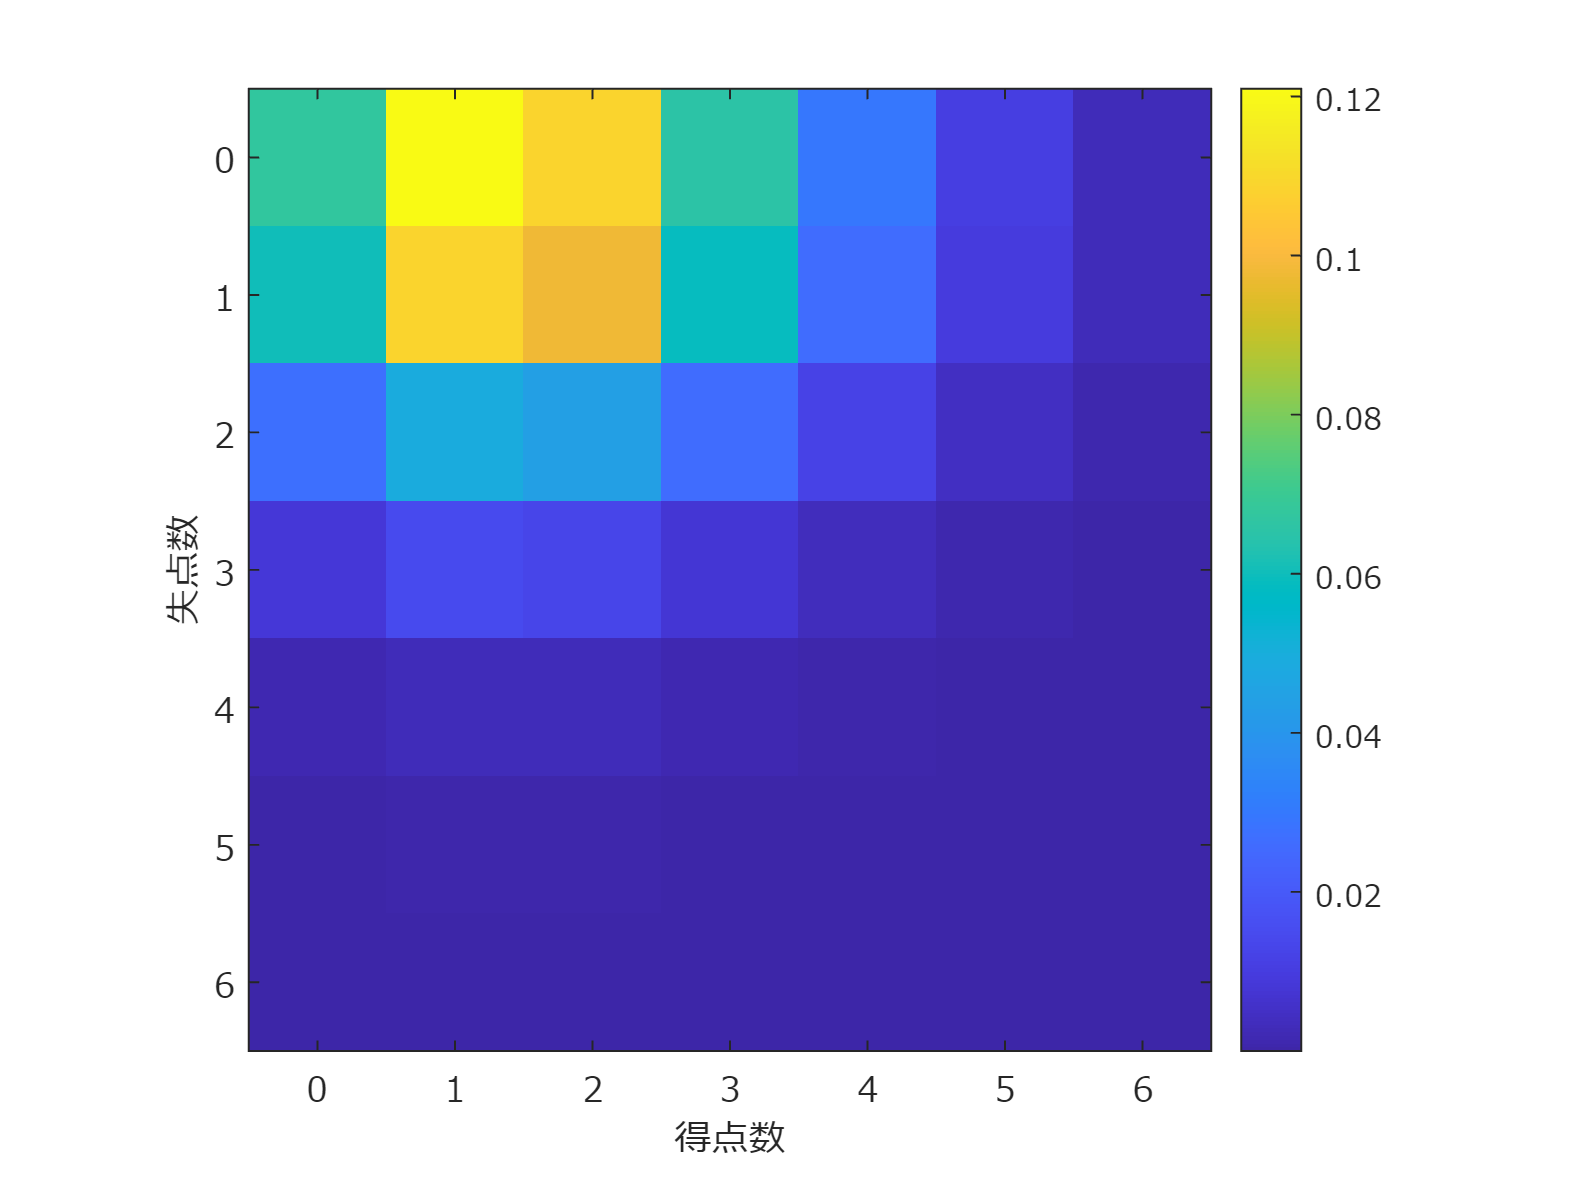

pMat=pGA'*pGF;
figure;
imagesc(bins,bins,pMat);axis equal;colorbar;
axis([-0.5 6.5 -0.5 6.5]);
set(gca,'fontname','メイリオ');
xlabel('得点数');ylabel('失点数');xticks(bins);yticks(bins);

% exportgraphics(gcf,'fig_poissonSimulator-prob.pdf');

勝ち・引き分け・負けそれぞれの確率を合計する．

pWin=sum(triu(pMat,1),'all')    %1行上にずらした上三角部分を取り出し，すべて足す

pWin = 0.5861

pDraw=sum(diag(pMat))   %対角要素を取り出し，すべて足す

pDraw = 0.2290

pLose=sum(tril(pMat,-1),'all')  %1行下にずらした下三角部分を取り出し，すべて足す

pLose = 0.1850

確率の合計が1となることを確認．

pWin+pDraw+pLose

ans = 1.0000

設定した試合数後の予測勝点の分布を計算して，1試合の予測勝率とともに図示する．

q=1;
for n1=1:numMatches
    q=conv(q,[pLose, pDraw, 0, pWin]);
end

予測平均勝点

q*(0:3*numMatches)'

ans = 67.5640

ind = cumsum(q)>=0.05 & cumsum(q)<=0.95;
bins=0:3*numMatches;

90％の確率で実際の勝点が含まれる範囲

[min(bins(ind)) max(bins(ind))]

ans =     55    78


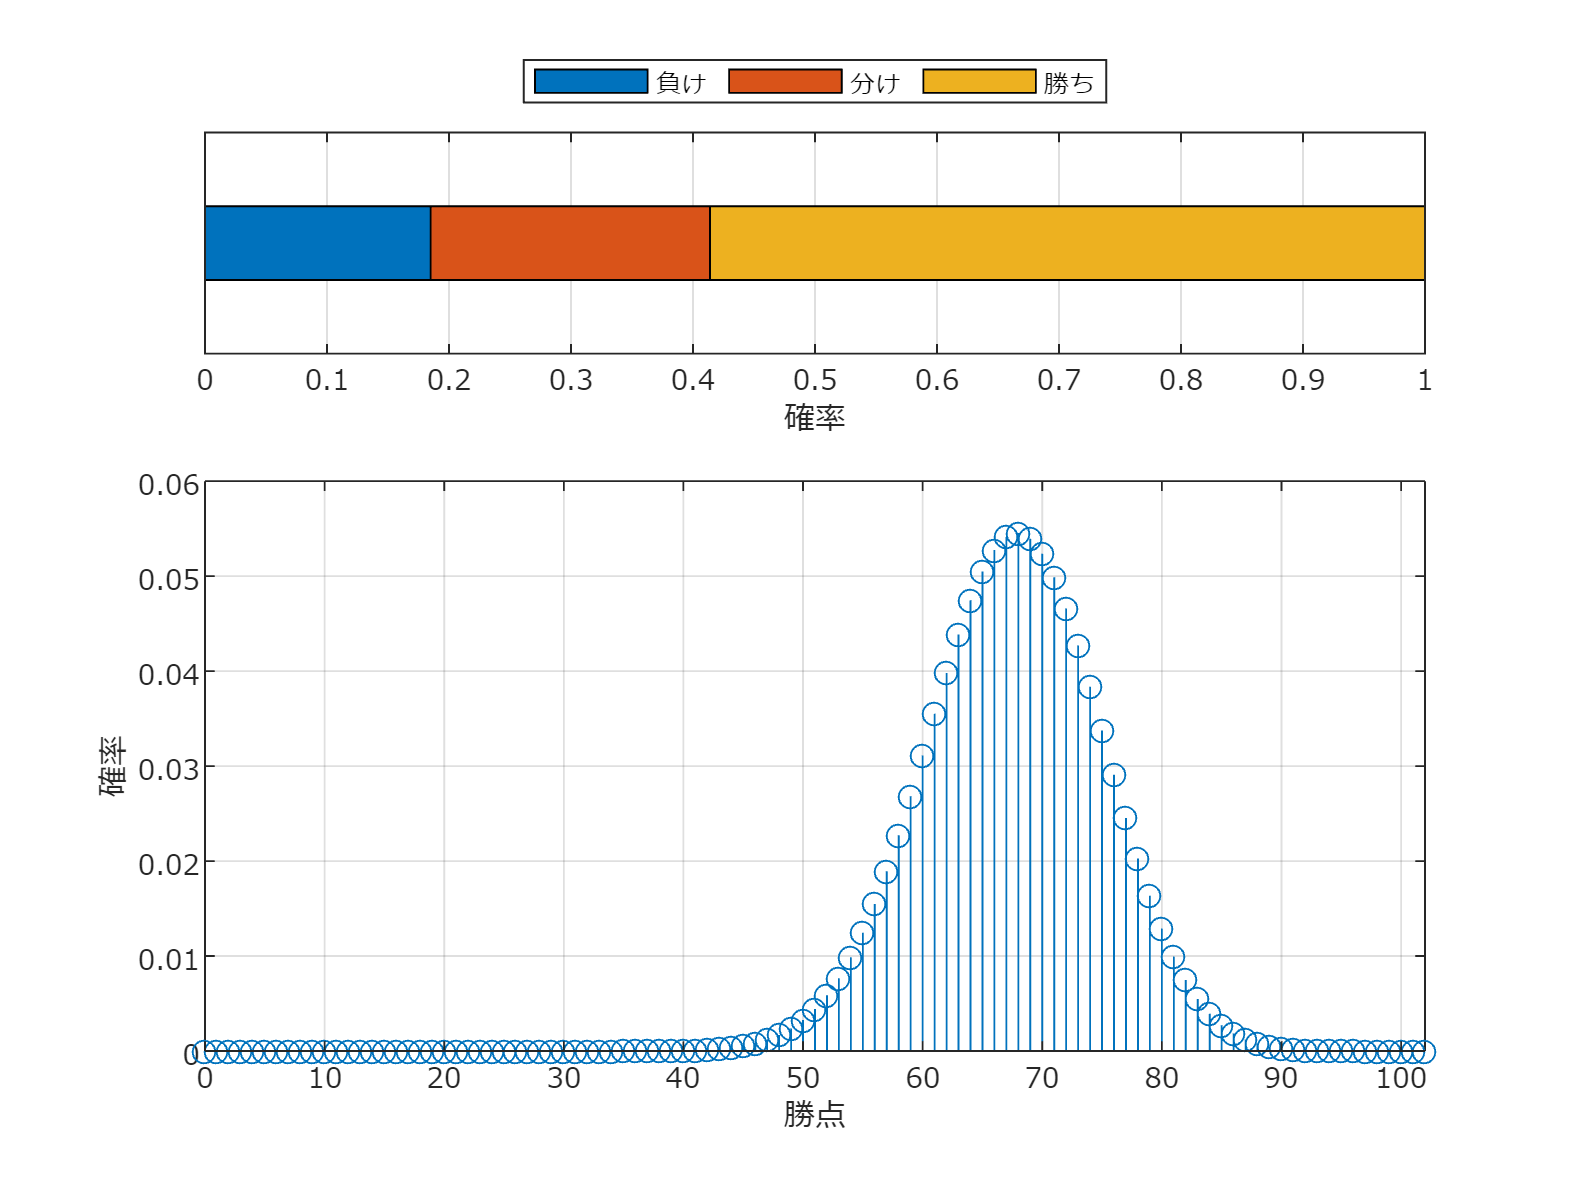

figure
tiledlayout(3,1);
nexttile;
barh(1,[pLose pDraw pWin],'stacked');grid on;
set(gca,'fontname','メイリオ');yticks([])
xlabel('確率');
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
nexttile([2,1]);
stem(0:3*numMatches,q,'o');xlim([0 3*numMatches]);
set(gca,'fontname','メイリオ');grid on;
xlabel('勝点');ylabel('確率');
% exportgraphics(gcf,'fig_poissonSimulator-points.pdf');